clear;
clc;

load magdata.mat;
y=con2seq(y);
u=con2seq(u);

d1=[1:10];
d2=[1:10];

% narxnet(inputDelays,feedbackDelays,hiddenSizes,feedbackMode,trainFcn)

[X,T]=simpleseries_dataset;
XTrain=X(1:80);
TTrain=T(1:80);
XPredict=X(81:100);

net=narxnet(1:2,1:2,10);

[Xs,Xi,Ai,Ts]=preparets(net,XTrain,{},TTrain);

net=train(net,Xs,Ts,Xi,Ai);
[Y,Xf,Af]=net(Xs,Xi,Ai);
perf=perform(net,Ts,Y)

perf =      0.017776



[netc,Xic,Aic]=closeloop(net,Xf,Af);
Yc = netc(XPredict,Xic,Aic)

Yc = 1×20 cell 数组
    {[0.11388]}    {[0.031379]}    {[-0.11437]}    {[-0.0010637]}    {[0.0094671]}    {[-0.13635]}    {[0.21173]}    {[-0.20053]}    {[-0.17653]}    {[0.14412]}    {[-0.086546]}    {[0.093917]}    {[0.14715]}    {[0.12603]}    {[-0.049531]}    {[-0.20281]}    {[0.28406]}    {[0.033637]}    {[0.16864]}    {[0.073555]}


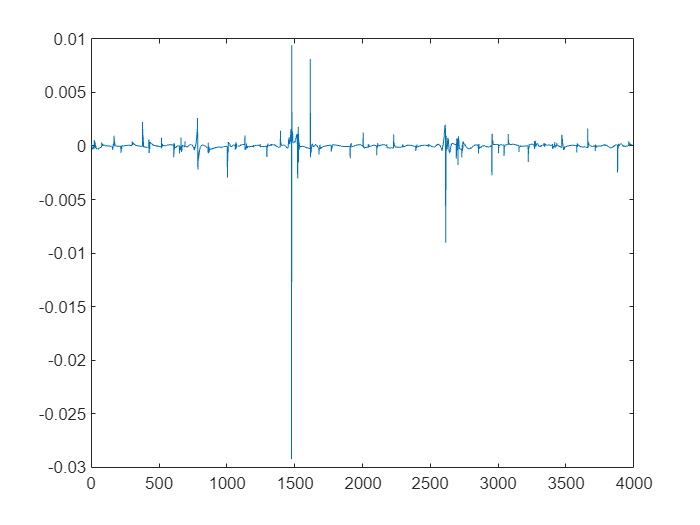

narx_net=narxnet(d1,d2,10);
narx_net.divideFcn='';
narx_net.trainParam.min_grad=1e-10;
[p,Pi,Ai,t]=preparets(narx_net,u,{},y); %转换后的输入p, 转换后的输出t。

narx_net=train(narx_net,p,t,Pi);
yp=sim(narx_net,p,Pi);
e=cell2mat(yp)-cell2mat(t);
figure(1);
plot(e);

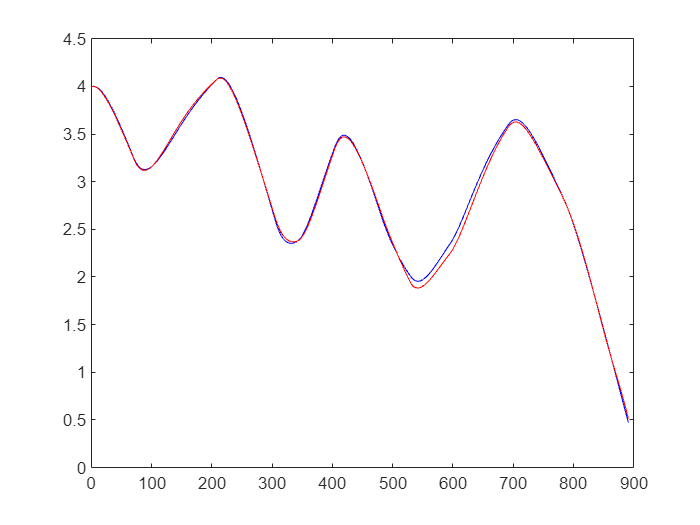

narx_net_closed=closeloop(narx_net);
y1 = y(1700:2600);
u1 = u(1700:2600);
[p1,Pi1,Ai1,t1] = preparets(narx_net_closed,u1,{},y1);
yp1 = narx_net_closed(p1,Pi1,Ai1);
TS = size(t1,2);
figure(2);
plot(1:TS,cell2mat(t1),'b',1:TS,cell2mat(yp1),'r')